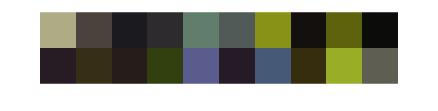

%3.1
clear
load("chips20.mat")
load("illum.mat")
load("xyz.mat")
% Compute Raw
dRaw=xyz'*(chips20.*CIED65)';
%e = R .* I
eD65=ones(1,61).*CIED65;
% Normalization
d=xyz'*(eD65)';
% Apply normalization (d' = d./e)

XYZ_D65_ref=dRaw./d;
showRGB(XYZ_D65_ref')


save("XYZ_D65_ref.mat","XYZ_D65_ref")

%3.2
clear
load("RGB_cal_D65.mat")
load("M_XYZ2RGB.mat")
load("XYZ_D65_ref.mat")
XYZ_cal_D65=(pinv(M_XYZ2RGB)*RGB_cal_D65);
% XYZ to Lab elementwise
[L,a,b]=xyz2lab(XYZ_cal_D65(1,:),XYZ_cal_D65(2,:),XYZ_cal_D65(3,:));
[L2,a2,b2]=xyz2lab(XYZ_D65_ref(1,:),XYZ_D65_ref(2,:),XYZ_D65_ref(3,:));

% Mean square error
diff_REF_CAL=sqrt(abs((L-L2).^2+(a-a2).^2+(b-b2).^2));
max(diff_REF_CAL)

ans = 84.1651

mean(diff_REF_CAL)

ans = 56.8180

%3.3
clear
colorRange=(400:5:700);
load("Ad.mat")
load("xyz.mat")
mycolors = [1 0 0; 0 1 0; 0 0 1];
ax=gca;
ax.ColorOrder=mycolors;

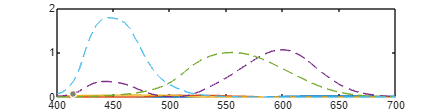

plot(colorRange,Ad)
hold on
plot(colorRange,xyz,'--')
hold off